# Using Signal Designer

[**Signal Designer**](matlab:open('SignalDesigner.m')) lets you define a signal trace using simple parameterization scheme to define the shape of a signal. Signal Designer can create two types of signals. One is a continuous multi-step signal which consists of smoothly connected flat segments generated by Akima interpolation. The other is a piece-wise constant signal. This Live Script shows an example use of Signal Designer in MATLAB.

Accompanying [**Signal Source Block Library**](matlab:open('SignalSourceBlockLibrary')) uses Signal Designer to provide **Continuous Multi-Step block** and **Piece-Wise Constant block** for use in Simulink as a signal source.

## Continuous Multi-step

Create a Signal Designer object to create a continuous multi-step signal trace.

smoothSignal = SignalDesigner("continuous");

Set an N-by-3 matrix for data points characterizing a continuous signal trace. In each row, a flat segment starts from first column and ends at second column in X (horizontal) axis. Third column defines a constant value in Y (vertical) axis. Second column can be NaN which defines a value at point (X, Y).

smoothSignal.XYData = [
  0    1  2 ;   ... a flat segment from 0 to 1 in X, of value 2 in Y
  4  nan  9 ;   ... a point at 4 in X, of value 9 in Y
  7   10  5 ];    % a flat segment from 7 to 10 in X, of value 5 in Y

Set a resolution of interpolation.

smoothSignal.DeltaX = 0.1;

Call the update function to generate a signal trace data set in the Signal Designer object.

update(smoothSignal)
disp(smoothSignal.Data(1:5, :))

     X       Y   
    ___    ______

      0         2
      1         2
    1.1    2.0228
    1.2    2.0892
    1.3     2.196



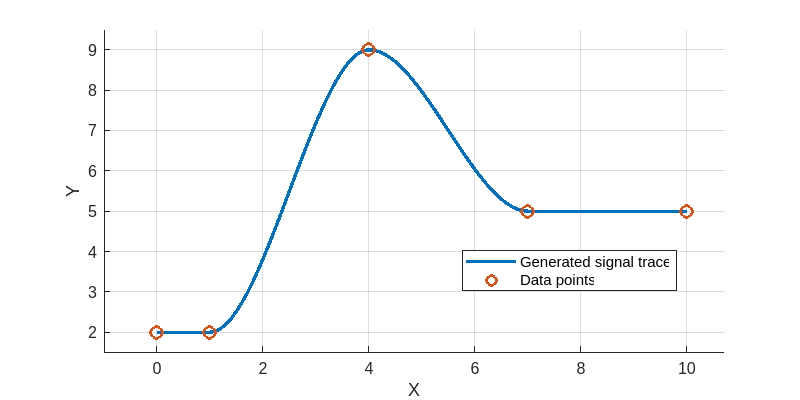

plotDataPoints(smoothSignal);

A Signal Designer object has properties which you can modify.

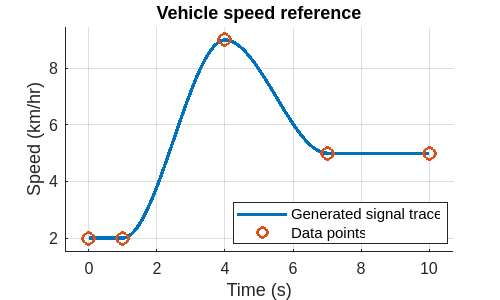

smoothSignal.XName = "Time";
smoothSignal.XUnit = "s";

smoothSignal.YName = "Speed";
smoothSignal.YUnit = "km/hr";

smoothSignal.Title = "Vehicle speed reference";

% Make sure to call update to reflect new property values.
update(smoothSignal)

% Figure object is returned.
fig = plotDataPoints(smoothSignal);
fig.Position(3:4) = [500 300];  % width height

## Piece-Wise Constant

Create a Signal Designer object to create a picewise constant signal trace.

stepSignal = SignalDesigner("step");

Set an N-by-2 matrix for data points characterizing a step signal trace. In each row, a flat segment starts from first column and ends at second column in X (horizontal) axis. Third column defines a constant value in Y (vertical) axis. Second column can be NaN which defines a value at point (X, Y).

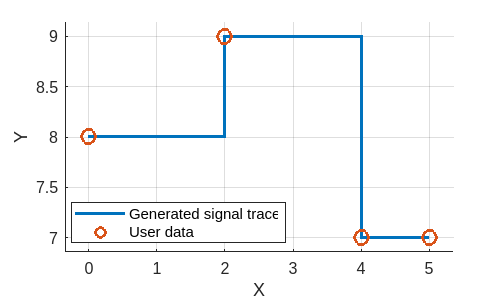

stepSignal.XYData = [
  0  8 ;  ... a constant segment from 0 in X, of value 8 in Y
  2  9 ;  ... a constant segment from 2 in X, of value 9 in Y
  4  7 ;  ... a constnat segment from 4 in X, of value 7 in Y
  5  7 ];   % a constnat segment from 5 in X, of value 7 in Y
update(stepSignal)
fig = plotDataPoints(stepSignal);
fig.Position(3:4) = [500 300];  % width height

*Copyright 2022-2023 The MathWorks, Inc.*